## ACTIVE VIBRATION CONTROL OF A FLEXIBLE STRUCTURE

### Uncontrolled System

clear all
clc
close all

n = 3;
k = 2;

M = eye(n);

w = [1.3164 ; 11.243 ; 13.944]*2*pi;
epsilon = [0.0067 ; 0.01 ; 0.002];

theta = [-0.387e-3 -0.387e-3
         -0.317e-2 -0.317e-2
         -0.776e-3 0.785e-3];

phi = [0.645 -0.4056  0.5205
       0.645 -0.4064 -0.5278
       0.207  0.769  -0.0045];

K = diag(w.^2);
D = diag(2*epsilon)*sqrt(K*M);

A = [zeros(n) eye(n)
     -inv(M)*K -inv(M)*D];

B = [zeros(n,k) ; inv(M)*theta];

C = [phi zeros(n) ; zeros(n) phi];

D = zeros(2*n,k);

sys = ss(A,B,C,D)

sys =
 
  A = 
            x1       x2       x3       x4       x5       x6
   x1        0        0        0        1        0        0
   x2        0        0        0        0        1        0
   x3        0        0        0        0        0        1
   x4   -68.41        0        0  -0.1108        0        0
   x5        0    -4990        0        0   -1.413        0
   x6        0        0    -7676        0        0  -0.3505
 
  B = 
              u1         u2
   x1          0          0
   x2          0          0
   x3          0          0
   x4  -0.000387  -0.000387
   x5   -0.00317   -0.00317
   x6  -0.000776   0.000785
 
  C = 
            x1       x2       x3       x4       x5       x6
   y1    0.645  -0.4056   0.5205        0        0        0
   y2    0.645  -0.4064  -0.5278        0        0        0
   y3    0.207    0.769  -0.0045        0        0        0
   y4        0        0        0    0.645  -0.4056   0.5205
   y5        0        0        0    0.645  -0.4064 

### Controlled System

rank(ctrb(A,B))

ans = 6


u1 = 5e-3;
u2 = 4.5e-3;
u3 = 1e-3;

initial_conditions = [u1 ; u2 ; u3 ; zeros(n,1)];

Qw = [1e3 ; 10 ; 1e3 ; 1e3 ; 10 ; 1e3];
Q = diag(Qw)

Q =         1000           0           0           0           0           0
           0          10           0           0           0           0
           0           0        1000           0           0           0
           0           0           0        1000           0           0
           0           0           0           0          10           0
           0           0           0           0           0        1000


R = 1*eye(k)

R =      1     0
     0     1


P = 1000;

[Gain,~,~] = lqr(sys,Q,R);

model_sys = P*sys;
feedback_sys = Gain*inv(C);

CL_sys = feedback(model_sys,feedback_sys)

CL_sys =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1           0           0           0           1           0           0
   x2           0           0           0           0           1           0
   x3           0           0           0           0           0           1
   x4      -68.41  -1.446e-05   8.048e-06      -1.474   -0.008685    0.004958
   x5    -0.01792       -4990   6.592e-05      -11.16      -1.484     0.04061
   x6   2.519e-05  -1.563e-07       -7676     0.01584    0.000101      -2.085
 
  B = 
           u1      u2
   x1       0       0
   x2       0       0
   x3       0       0
   x4  -0.387  -0.387
   x5   -3.17   -3.17
   x6  -0.776   0.785
 
  C = 
            x1       x2       x3       x4       x5       x6
   y1    0.645  -0.4056   0.5205        0        0        0
   y2    0.645  -0.4064  -0.5278        0        0        0
   y3    0.207    0.769  -0.0045        0        0        0
   y4        0        0 

## Comparison

damp(sys)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -5.54e-02 + 8.27e+00i     6.70e-03       8.27e+00         1.80e+01    
 -5.54e-02 - 8.27e+00i     6.70e-03       8.27e+00         1.80e+01    
 -7.06e-01 + 7.06e+01i     1.00e-02       7.06e+01         1.42e+00    
 -7.06e-01 - 7.06e+01i     1.00e-02       7.06e+01         1.42e+00    
 -1.75e-01 + 8.76e+01i     2.00e-03       8.76e+01         5.71e+00    
 -1.75e-01 - 8.76e+01i     2.00e-03       8.76e+01         5.71e+00    


damp(CL_sys)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -7.37e-01 + 8.24e+00i     8.91e-02       8.27e+00         1.36e+00    
 -7.37e-01 - 8.24e+00i     8.91e-02       8.27e+00         1.36e+00    
 -7.42e-01 + 7.06e+01i     1.05e-02       7.06e+01         1.35e+00    
 -7.42e-01 - 7.06e+01i     1.05e-02       7.06e+01         1.35e+00    
 -1.04e+00 + 8.76e+01i     1.19e-02       8.76e+01         9.59e-01    
 -1.04e+00 - 8.76e+01i     1.19e-02       8.76e+01         9.59e-01    


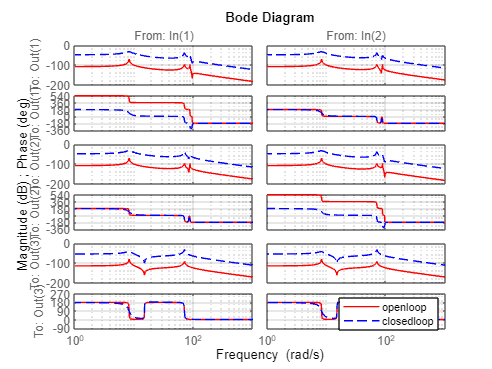


bode(sys(1:3,:),'r',CL_sys(1:3,:),'b--')
legend('openloop','closedloop')
grid on